240032 ExFinal Q1 2022-23 Problema 1, cas A

## Problem 1

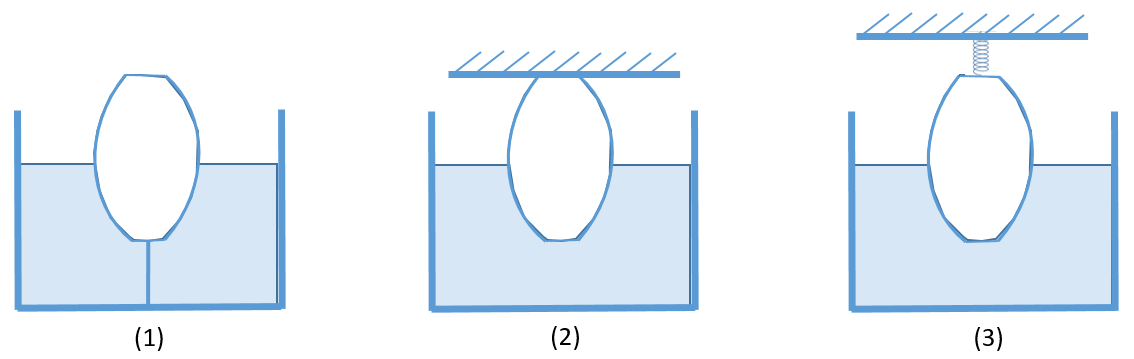

A buoy of length $L = 4$, made of an elastic material of Young’s modulus $E$ and negligible weight, is roped at the end $x=0$ to the bottom of a container and submerged up to $x=L/2$ in a fluid of specific weight $w$, as it is displayed in the figure above (left). 

The area of the transversal section of the buoy is $A(x)$, and the buoy is symmetric with respect to $x=L/2$ (i.e. $A(x) =A(L-x)$). Moreover, for the particular transversal section of the buoy, we know  that (pay attention to the limits of integration), 


$$\int _0^{L/2}\!\!\! A(x) \:\!{\rm d}x=\int _0^{L/2}\!\!\! xA(x)\:\! {\rm d}x = \alpha$$


(being $\alpha$ a known value). 

Consider just one 1D linear finite element$\Omega^{1} = [0,L]$ to approximate the elongation of the buoy when submerged, and note that the **external force** applied per unit of length exercised by the fluid on the buoy is


$$f(x) = A(x)w,$$


only applied to the submerged part.

#### Questions

clearvars
close all

length = 4;   
point = 1;  %the point where the Psi1 is evaluated in part (a)


(a) (1 point) The value of $\Psi^{1}_{1}(1)$ is. 

**Solution.** $\Psi^{1}_{1}(x) = \frac{L-x}{L}$.

syms x L
Psi11(x,L) = (L-x)/L; Psi12(x,L) = x/L;
fprintf('*** So, for L = %.2f, and x = %s, the answer of question (a) is %s\n',...
    length,rat(point),Psi11(point,length))

*** So, for L = 4.00, and x = 1, the answer of question (a) is 3/4


**Remark.  **Note that the other shape function of the element is $\Psi^{1}_{2}(x) = \frac{x}{L}$.

(b) (1 point) The value of $K_{11}$ is.

**Solution.**

 
$$K_{11} = K^{1}_{11} = \int_{0}^{L} EA(x) \frac{\mathrm{d}\Psi^{1}_{1}}{\mathrm{d} x}(x)\frac{\mathrm{d}\Psi^{1}_{1}}{\mathrm{d}x} (x)\:\mathrm{d} x = \frac{E}{L^{2}}\int_{0}^{L} A(x)\:\mathrm{d} x = 
\frac{E}{L^{2}}\int_{0}^{L/2} A(x)\:\mathrm{d} x + \frac{E}{L^{2}}\int_{L/2}^{L} A(x)\:\mathrm{d}x $$


Using the property $\displaystyle \int _0^{L/2}A(x) {\rm d}x=\int _0^{L/2}xA(x) {\rm d}x = \alpha$ and the change $y = L - x$, we can see that, due to the symmetry, the last integral equals $\displaystyle \int_{0}^{L/2}\!\!\! A(x)\:\!\mathrm{d} x$. Indeed,


$$\int_{L/2}^{L}\!\!\! A(x)\:\!\mathrm{d} x = -\int_{L/2} ^{0}\!\!\! A(L-y)\:\!\mathrm{d} y = \int_{0}^{L/2}\!\!\! A(y)\:\!\mathrm{d} y.$$


So the answer of question (b) is $K_{11} = \frac{2\alpha E}{L^{2}}$.

**Remark. **Note that the stiffness matrix is then $K= \frac{2\alpha E}{L^{2}}\left(\begin{array}{rr} 1 & -1\\ -1 & 1\end{array}\right)$.

(c) (3 points) Let us define $\eta = w/E$. The elongation of the buoy is.

**Solution.** First, we have to find the load vector$F$,


$$\begin{array}{ll}
F_{1}\!\!\!\! &= F^{1}_{1} = \int_{0}^{L/2}\!\! f(x) \Psi_{1}^{1}(x)\:\!\mathrm{d} x = \frac{w}{L}\int_{0}^{L/2}\!\! (L-x) A(x)\:\!\mathrm{d} x = w\int_{0}^{L/2}\!\! A(x)\:\!\mathrm{d}x + \frac{w}{L}\int_{0}^{L/2} \!\! x A(x)\:\!\mathrm{d} x = \alpha w\left(1 - \frac{1}{L}\right),\\
F_{2}\!\!\!\! &= F^{1}_{2} = \int_{0}^{L/2}\!\! f(x)\Psi^{1}_{2}(x)\:\!\mathrm{d} x = \frac{w}{L}\int_{0}^{L/2}\!\! x A(x)\:\!\mathrm{d} x = \frac{\alpha w}{L},
\end{array}$$
 

or, in vetor notation. $\displaystyle F = \frac{\alpha w}{L}\left(\begin{array}{cc} L-1\\ 1\end{array}\right)$. 

**Remark. **We have used that,


$$\int _0^{L/2}\!\!\! A(x)\:\! {\rm d}x= \int _0^{L/2}\!\!\! xA(x) \:\!{\rm d}x = \alpha.$$


Therefore, the system to solve (the coupled system) is


$$\frac{2\alpha E}{L^{2}}\left(\begin{array}{cc} 1 & -1 \\ -1 & 1\end{array}\right)\left(\begin{array}{c} U_{1}\\ U_{2}\end{array}\right) = \frac{\alpha w}{L}\left(\begin{array}{cc} L-1\\ 1\end{array}\right)+ \left(\begin{array}{c} Q_{1}\\ Q_{2}\end{array}\right),
$$


With B.C. $Q_{2} = 0$ (essential), $U_{1} = 0$ (natural). Then, the reduced system turns out to be just a one single linear equation,


$$\frac{2\alpha E}{L^{2}} U_{2} = \frac{\alpha w}{L},$$


so $U_{2} = \frac{wL}{2E} = \frac{\eta L}{2}$, and hence the elongation, $\Delta:=U_{2}-U_{1} = \frac{\eta L}{2} - 0 =\frac{\eta L}{2}$.

syms eta
fprintf('*** So, for L = %.2f, the answer of question (c) is %s\n',length,eta*length/2)

*** So, for L = 4.00, the answer of question (c) is 2*eta


 (d) (2 points) Consider the same buoy, again submerged up to $x = L/2$, but now without the rope and being the top of the buoy stopped by the  ceiling (central figure). Using again a linear 1D finite element, the  contraction of the buoy is.

**Solution. **We have the same coupled system as in (c), but now the B.C. are $Q_{1} = 0$ (natural) and $U_{2} = 0$ (essential). Hence, the reduced system is now,


$$\frac{2\alpha E}{L^{2}}U_{1} = \frac{\alpha w}{L}\left(L-1\right).$$


This yields $U_{1} = \frac{wL}{2E}\left(L-1\right) = \frac{L\left(L-1\right)}{2}\eta$, and the corresponding elongation is


$$\Delta:= U_{2} - U_{1} = 0 -  \frac{L\left(L-1\right)}{2}\eta = -\frac{L\left(L-1\right)}{2}\eta,$$


and we shall give the *contraction *as its absolute value. 

fprintf('*** So, for L = %.2f, the answer of question (d) is %s\n',length,eta*length*(length-1)/2)

*** So, for L = 4.00, the answer of question (d) is 6*eta


(e) (3 points)  Assume now that the buoy hangs from the ceiling with a spring of constant *𝑘* and the container is then filled with the fluid till $x = L/2$ of the buoy (right figure). The displacement $U_{1}$ is.

**Solution. **Again, the coupled system is the same as in (c), but now we only have natural B.C.: $Q_{1} = 0$, $Q_{2} = -k U_{2}$ (this last, due to the action of the spring). Therefore, the system to solve is 


$$\frac{2\alpha E}{L^{2}}\left(\begin{array}{cc} 1 & -1 \\ -1 & 1\end{array}\right)\left(\begin{array}{c} U_{1}\\ U_{2}\end{array}\right) = \frac{\alpha w}{L}\left(\begin{array}{cc} L-1\\ 1\end{array}\right)+ \left(\begin{array}{c} 0\\ -kU_{2}\end{array}\right).$$


If we divide this last equation by $\frac{2\alpha E}{L^2}$, and then move the term $-\frac{k L^{2}}{2\alpha E} \left(\begin{array}{c} 0\\U_{2}\end{array}\right)$to the lhs, we get, taking into account that $\eta = \frac{w}{E}$, the following system of linear equations: 


$$\begin{array}{rl}
U_{1} - U_{2} &\!\!\!\!\!= \eta\frac{L\left(L-1)}{2},\\
-U_{1} +\left(1 + \frac{kL^{2}}{2\alpha E}\right)U_{2} &\!\!\!\!\! = \eta \frac{L}{2}.
\end{array}$$


Adding up the above two equations one finds $U_{2} = \frac{\alpha \eta E}{k} = \frac{\alpha w}{k}$ (recall that $\eta = w/E$). Finally, substitution of this value for $U_{2}$ in the first equation yields,


$$U_{1} = U_{2} + \eta\frac{L\left(L-1\right)}{2} = \frac{\alpha w}{k} + \eta\frac{L\left(L-1\right)}{2}.$$


fprintf('*** So, for L = %.2f, the answer is of question (e) is alpha·w/k + %s\n',length,eta*length*(length-1)/2)

*** So, for L = 4.00, the answer is of question (e) is alpha·w/k + 6*eta
